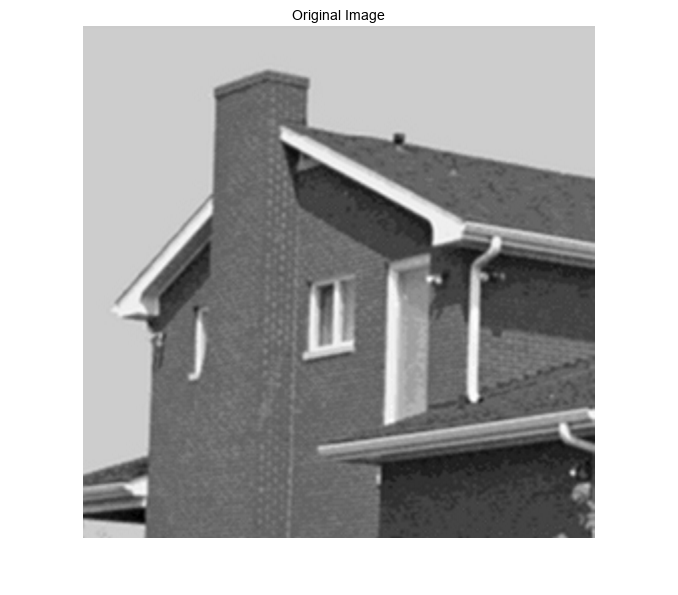

% Load the image
img = imread('images/house.tif');

% Define the LoG filters with different sigma values
sigma1 = 1;
sigma2 = 2;
sigma3 = 3;
% ksize = 7;
% Apply the LoG filters to the image
LoG1_img = my_conv(img,  my_LoG_kernel(2*floor(3*sigma1)+1, sigma1));
LoG2_img = my_conv(img,  my_LoG_kernel(2*floor(3*sigma2)+1, sigma2));
LoG3_img = my_conv(img,  my_LoG_kernel(2*floor(3*sigma3)+1, sigma3));


% Apply unsharp mask to the image with different k values
k = 5;
unsharp_mask = img - my_conv(img, my_Gaussian_kernel(5, 3));
ImgUnsharp = img + k * unsharp_mask;

% Display the original image and the sharpened images
figure;
figure; imshow(img); title('Original Image');

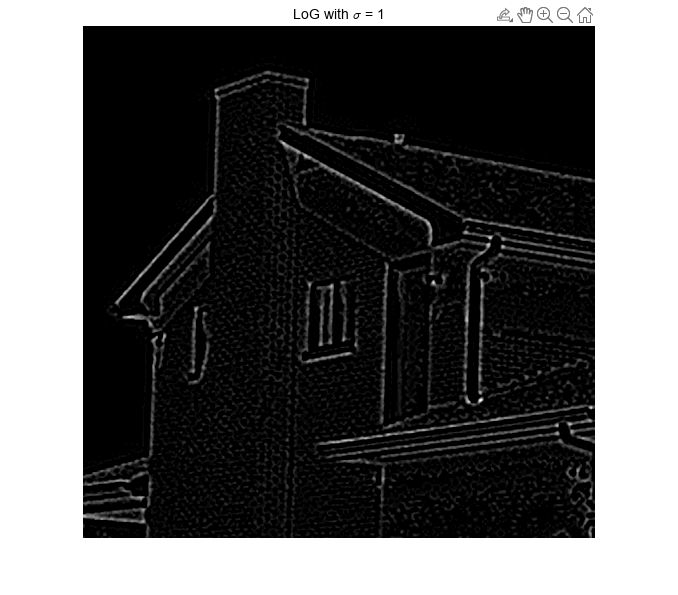

figure; imshow(LoG1_img, []); title(['LoG with \sigma = ' num2str(sigma1)]);

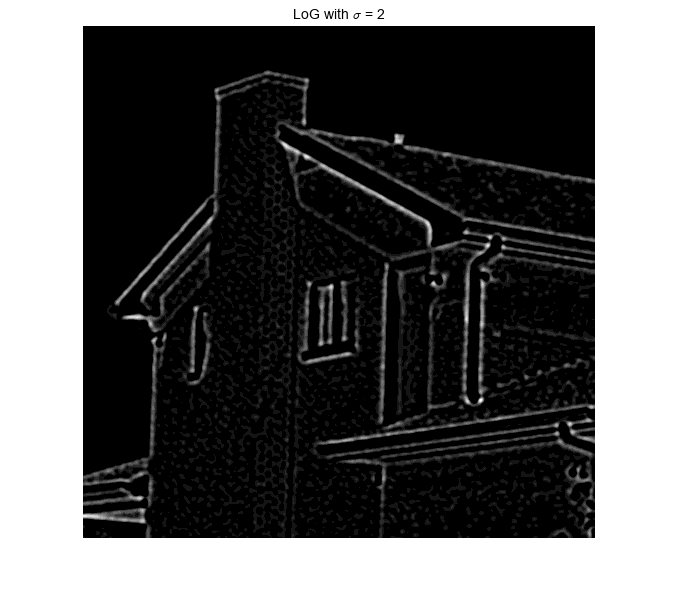

figure; imshow(LoG2_img, []); title(['LoG with \sigma = ' num2str(sigma2)]);

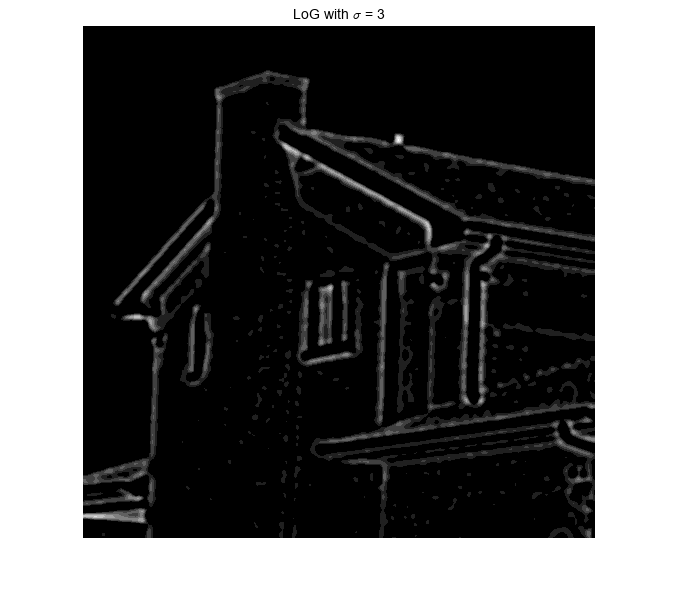

figure; imshow(LoG3_img, []); title(['LoG with \sigma = ' num2str(sigma3)]);

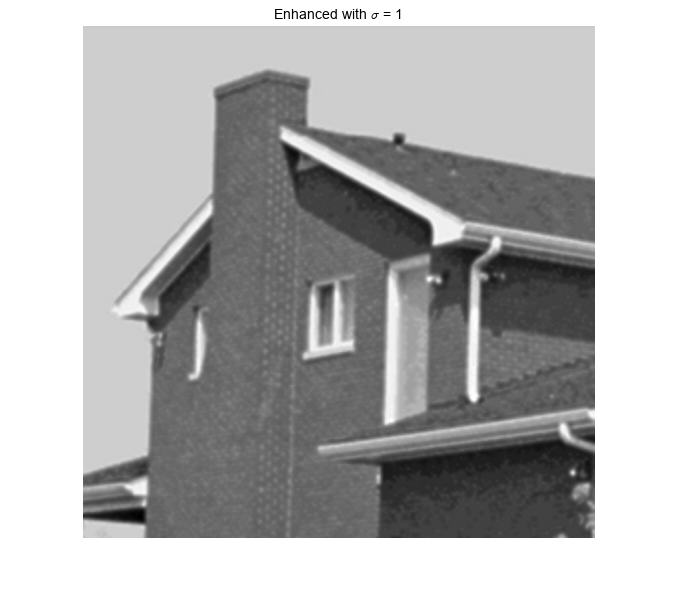

figure; imshow(LoG1_img+img, []); title(['Enhanced with \sigma = ' num2str(sigma1)]);

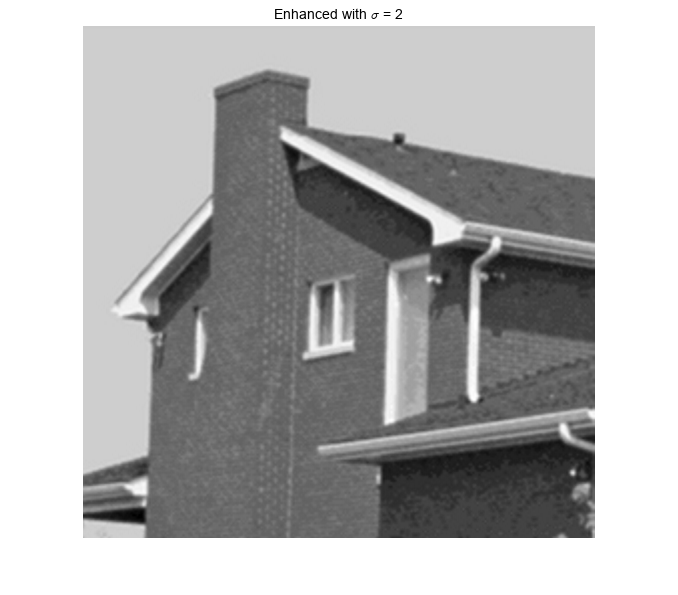

figure; imshow(LoG2_img+img, []); title(['Enhanced with \sigma = ' num2str(sigma2)]);

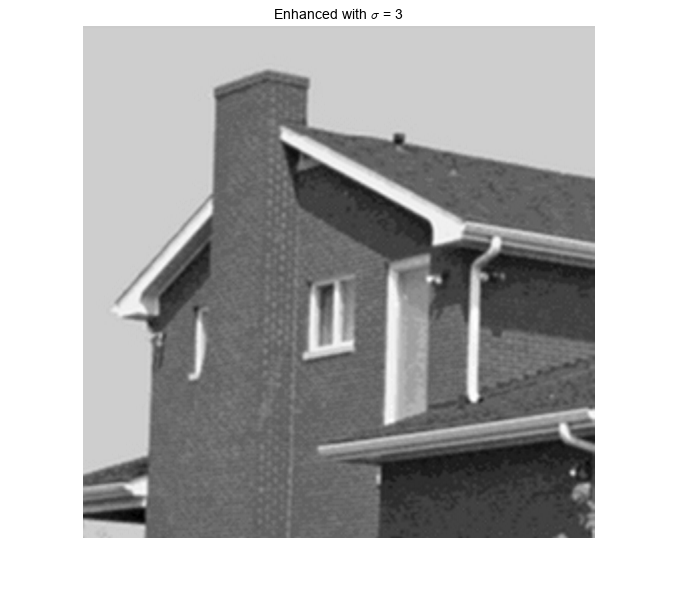

figure; imshow(LoG3_img+img, []); title(['Enhanced with \sigma = ' num2str(sigma3)]);

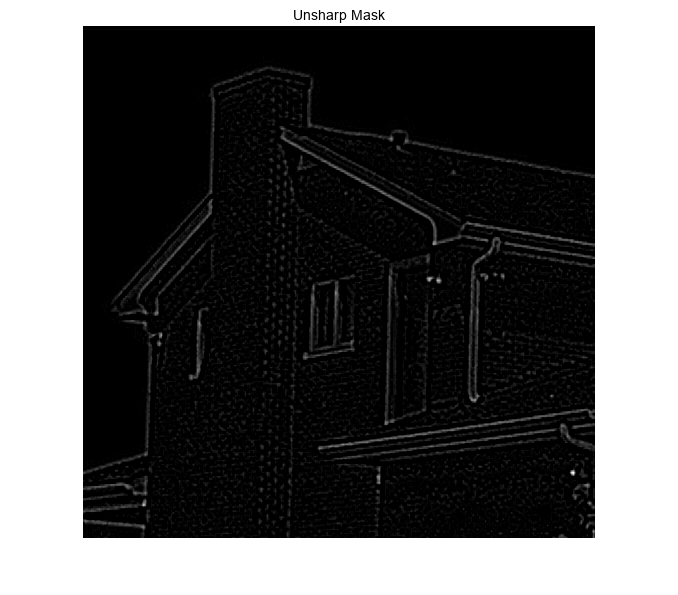

figure; imshow(unsharp_mask, []); title('Unsharp Mask');

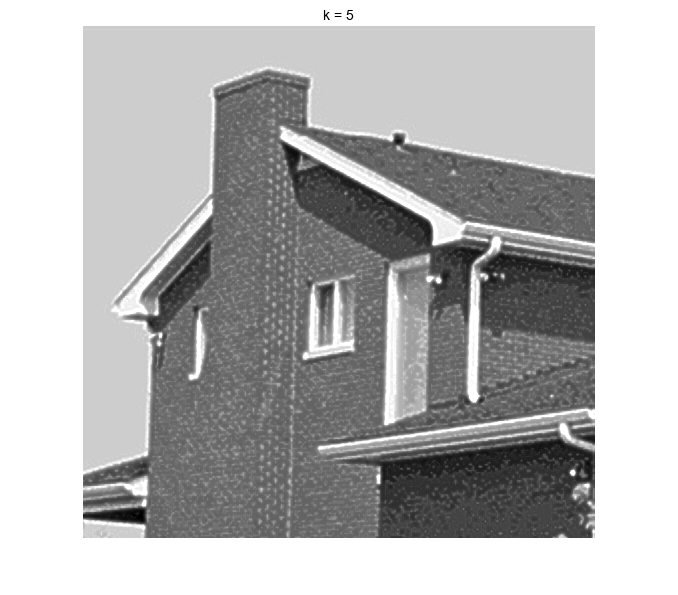

figure; imshow(ImgUnsharp, []); title(['k = ' num2str(k)]);

function [result] = my_conv(M, K)
result = zeros(size(M)+(size(K)-1));
M_pad = padarray(M, (size(K)-1), 'replicate');
M_pad = double(M_pad);
for i = 1:size(result,1)
    for j =1:size(result,2)
        M_crop = M_pad(i:i+size(K,1)-1,j:j+size(K,2)-1);
        for m = 1:size(K, 1)
            for n = 1:size(K, 2)
                result(i,j)=result(i,j)+M_crop(m,n)*K(size(K,1)-m+1, size(K,2)-n+1);
            end
        end
    end
end
t = floor(size(K,1) / 2);
result = result(1+t:size(result, 1)-t, 1+t:size(result, 2)-t);
result = uint8(result);
end

function [log_kernel] = my_LoG_kernel(ksize, sigma)
% matrix
[x, y] = meshgrid(-(ksize-1)/2:(ksize-1)/2, -(ksize-1)/2:(ksize-1)/2);
% function
log_kernel = (-1/(pi*sigma^4)) * (1 - ((x.^2 + y.^2)/(2*sigma^2))) .* exp(-(x.^2 + y.^2)/(2*sigma^2));
% normalize -> 0
log_kernel = log_kernel - sum(log_kernel(:))/(ksize^2);
end

function [gaussian_kernel] = my_Gaussian_kernel(ksize, sigma)
% matrix
[x, y] = meshgrid(-(ksize-1)/2:(ksize-1)/2, -(ksize-1)/2:(ksize-1)/2);
% function
gaussian_kernel = exp(-(x.^2 + y.^2)/(2*sigma^2));
% normalize -> 1
gaussian_kernel = gaussian_kernel / sum(gaussian_kernel(:));
end